# Homework 1

## Task 1

### a) Read a raw image

Read the image with:

- pixel size 512x512

- unsigned integer with 16 bits

- big-endian encoding

im_0069 = fread(fopen("data/IM_0069_rot.raw"), [512, 512], 'int16', 'ieee-be');

### b) Display the image with a colorbar

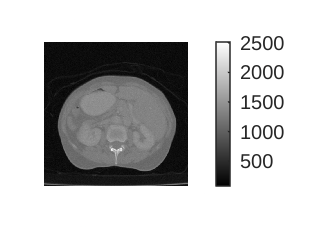

figure();
imshow(im_0069, []);
colorbar

### c) Measure the noise

Formula: 

standard_deviation(image_area) / mean(image_area)

image_width = 614.4

image_width = 614.4000

pixel_width = 512

pixel_width = 512

pixel_size_mm = image_width / pixel_width

pixel_size_mm = 1.2000

measurement_width_mm = 24

measurement_width_mm = 24

measurement_width_pixel = measurement_width_mm / pixel_size_mm

measurement_width_pixel = 20

measurement_pos_x = 210

measurement_pos_x = 210

measurement_pos_y = 180

measurement_pos_y = 180

This visualization is just added to show that a homogeneous area is chosen.

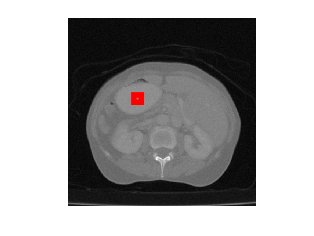

figure();
imshow(im_0069, []);
hold on;
rectangle("Position", [measurement_pos_y, measurement_pos_x, measurement_width_pixel, measurement_width_pixel], ...
          "EdgeColor", "r", "LineWidth", 2);
hold off;

measurement_area_im_0069 = im_0069(measurement_pos_x:measurement_pos_x + measurement_width_pixel, measurement_pos_y:measurement_pos_y + measurement_width_pixel);
measurement_area_im_0069_std = std(measurement_area_im_0069(:)) 

measurement_area_im_0069_std = 27.1393

measurement_area_im_0069_mean = mean(measurement_area_im_0069(:))

measurement_area_im_0069_mean = 1.4275e+03

im_0069_noise_estimation = measurement_area_im_0069_std / measurement_area_im_0069_mean

im_0069_noise_estimation = 0.0190

## Task 2

### a + b) Implement subsampling to 256x256

subsampled_im_size_x = 256;
subsampled_im_size_y = 256;

#### First approach

tic;
subsampled_im_0069 = zeros(subsampled_im_size_x, subsampled_im_size_y);
for x = 1:subsampled_im_size_x
    for y = 1:subsampled_im_size_y
        pixel_sample = [im_0069(x * 2 - 1, y * 2 - 1), im_0069(x * 2 - 1, y * 2), im_0069(x * 2, y * 2 - 1), im_0069(x * 2, y * 2)];
        subsampled_im_0069(x, y) = mean(pixel_sample);
    end
end
toc;

Elapsed time is 0.036977 seconds.


#### Second approach

tic;
subsampling_index_x = 1:2:size(im_0069, 1);
subsampling_index_y = 1:2:size(im_0069, 2);
subsampled_im_0069 = (im_0069(subsampling_index_x, subsampling_index_y) + im_0069(subsampling_index_x + 1, subsampling_index_y) + im_0069(subsampling_index_x, subsampling_index_y + 1) + im_0069(subsampling_index_x + 1, subsampling_index_y + 1)) / 4;
toc;

Elapsed time is 0.004307 seconds.


#### Time measurements

As expected, the second approach is much faster.

In one example run, approach one took 40 milliseconds while appraoch two finished after 4 milliseconds.

### c) Display the subsampled image

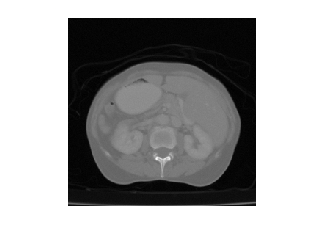

figure();
imshow(subsampled_im_0069, []);

### d)

measurement_width_subsampled_pixel = measurement_width_pixel / 2

measurement_width_subsampled_pixel = 10

measurement_pos_subsampled_x = measurement_pos_x / 2

measurement_pos_subsampled_x = 105

measurement_pos_subsampled_y = measurement_pos_y / 2

measurement_pos_subsampled_y = 90

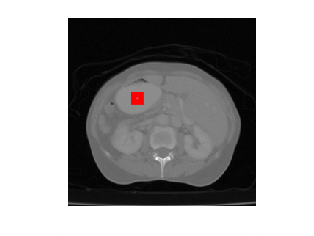

figure();
imshow(subsampled_im_0069, [])
hold on;
rectangle("Position", [measurement_pos_subsampled_y, measurement_pos_subsampled_x, measurement_width_subsampled_pixel, measurement_width_subsampled_pixel], ...
          "EdgeColor", "r", "LineWidth", 2);
hold off;

measurement_area_subsampled_im_0069 = subsampled_im_0069(measurement_pos_subsampled_x:measurement_pos_subsampled_x + measurement_width_subsampled_pixel, measurement_pos_subsampled_y:measurement_pos_subsampled_y + measurement_width_subsampled_pixel);
measurement_area_subsampled_im_0069_std = std(measurement_area_subsampled_im_0069(:)) 

measurement_area_subsampled_im_0069_std = 14.2814

measurement_area_subsampled_im_0069_mean = mean(measurement_area_subsampled_im_0069(:))

measurement_area_subsampled_im_0069_mean = 1.4269e+03

subsampled_im_0069_noise_estimation = measurement_area_subsampled_im_0069_std / measurement_area_subsampled_im_0069_mean

subsampled_im_0069_noise_estimation = 0.0100

### e) Caculate the noise reduction effect

(noise_original - noise_subsampled)/noise_original

noise_reduction_ratio = (im_0069_noise_estimation - subsampled_im_0069_noise_estimation) / im_0069_noise_estimation 

noise_reduction_ratio = 0.4736